**Ex 2.2.1 a)**

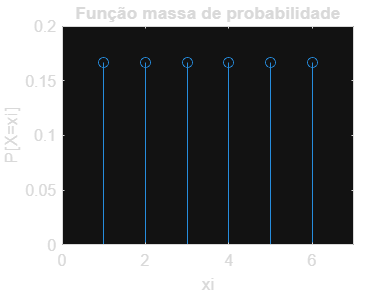

Sx = 1:6; %espaço de amostragem

prob = ones(1,6)/6;

stem(Sx,prob);
title("Função massa de probabilidade");
xlabel('xi');
ylabel('P[X=xi]');
axis([0 7 0 1/5]);

**Ex 2.2.1 b)**

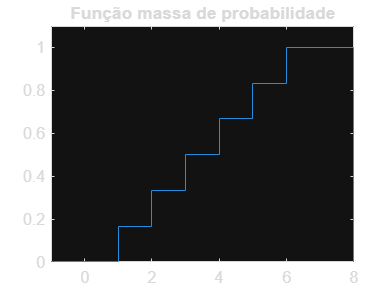

Sx = 1:6; %espaço de amostragem

prob = ones(1,6)/6;

px = cumsum(prob);
stairs([-1 Sx 8], [0 px 0])
title("Função massa de probabilidade");
axis([-1 8 0 1.1]);

**Ex 2.2.2 a)**

Espaço de amostragem = valor das notas (nota1, nota2, ..., nota100)

P(5euros) = 90/100

P(50euros) = 9/100

P(100euros) = 1/100

**Ex 2.2.2 b)**

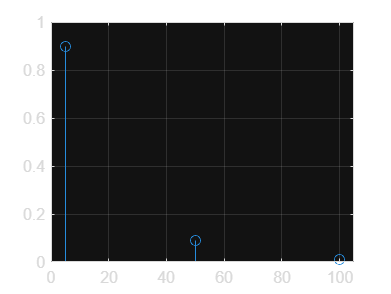

X = [5 50 100];
prob = [90 9 1]/100;

stem(X, prob);
axis([0 105 0 1]);
grid on

**Ex 2.2.2 c)**

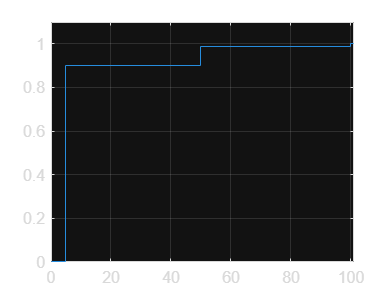

X = [5 50 100];
prob = [90 9 1]/100;

px = cumsum(prob);
stairs([0 X 101], [0 px 1]);
axis([0 101 0 1.1]);
grid on

**Ex 2.2.3 a)**

Sx = 0:4;

N = 1e5;
p = 1/2;
exp = rand(4, N) < p;

num0 = sum(sum(exp) == 0);
num1 = sum(sum(exp) == 1);
num2 = sum(sum(exp) == 2);
num3 = sum(sum(exp) == 3);
num4 = sum(sum(exp) == 4);

prob0 = num0/N;
prob1 = num1/N;
prob2 = num2/N;
prob3 = num3/N;
prob4 = num4/N;

fprintf("Px(0)= %.6f\nPx(1)= %.6f\nPx(2)= %.6f\nPx(3)= %.6f\nPx(4)= %.6f\n", prob0,prob1,prob2,prob3,prob4);

Px(0)= 0.062520
Px(1)= 0.249930
Px(2)= 0.374430
Px(3)= 0.250250
Px(4)= 0.062870


**Ex 2.2.3 b)**

Sx = 0:4;

N = 1e5;
p = 1/2;
exp = rand(4, N) < p;

num0 = sum(sum(exp) == 0);
num1 = sum(sum(exp) == 1);
num2 = sum(sum(exp) == 2);
num3 = sum(sum(exp) == 3);
num4 = sum(sum(exp) == 4);

prob0 = num0/N;
prob1 = num1/N;
prob2 = num2/N;
prob3 = num3/N;
prob4 = num4/N;

prob = [prob0 prob1 prob2 prob3 prob 4];

media = sum(Sx.*prob);

Arrays have incompatible sizes for this operation.

Related documentation

var = sum((Sx.^2).*prob) - (media.^2);
desvio_padrao = sqrt(var);

fprintf("Valor Esperado = %.6f \nVariância = %.6f \nDesvio padrão = %.6f\n", media, var, desvio_padrao)